GPU Check

gpuDeviceTable

ans = 1×5 table
    Index              Name               ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3070"          "8.6"               true              true      


Set GPU

gpuDevice(1)

ans =   CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589279232 (8.59 GB)
      AvailableMemory: 7443034112 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

Parameters

name = "AlexNet"

name = "AlexNet"

batch_size = 20

batch_size = 20

epochs = 1

epochs = 1

model_directory = strcat("RCNN/", name, "/MathLab_Data")

model_directory = "RCNN/AlexNet/MathLab_Data"

mkdir(model_directory)

%mkdir(model_directory + "/training")
%mkdir(model_directory + "/validation")
mkdir(model_directory + "/final_test_results")

Loading train ground truths

load("RCNN/GTTrain.mat")

Train model

options = trainingOptions('sgdm', ...
  'MiniBatchSize', batch_size, ...
  'InitialLearnRate', 1e-3, ...
  'MaxEpochs', epochs);

[net, info] = trainRCNNObjectDetector(GTTrain, "alexnet", options, "NegativeOverlapRange", [0 0.3]);

*******************************************************************
Training an R-CNN Object Detector for the following object classes:

* Edible
* Poisonous

--> Extracting region proposals from 1800 training images...done.



--> Training a neural network to classify objects in training data...

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       50.00% |       1.0168 |          0.0010 |
|       1 |          50 |       00:00:07 |       75.00% |       0.9983 |          0.0010 |
|       1 |         100 |       00:00:15 |       75.00% |       0.7116 |          0.0010 |
|       1 |         150 |       00:00:23 |       75.00% |       0.6989 |          0.0010 |
|       1 |         200 |       00:00:30 |       75.00% |       0.7385 |          0.0010 |
|       1 |         250 |       00:00:38 |     

Time : 

AlexNet : 7 min 14s

ResNet50 : 

GoogleNet :  

ArticleNet : 

Making examples

exmp_img = imread("Mushroom dataset\r-cnn\Edible\img0149.jpg");

[bbox, score, label] = detect(net, exmp_img, MiniBatchSize=20)

bbox =     97    39   114   201


score = single
0.9997

label = categorical
     Edible 


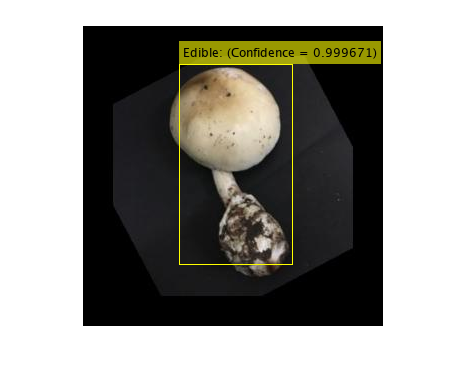

[score, idx] = max(score);

bbox = bbox(idx, :);
annotation = sprintf('%s: (Confidence = %f)', label(idx), score);

detectedImg = insertObjectAnnotation(exmp_img, 'rectangle', bbox, annotation);

figure
imshow(detectedImg)

Export example

imwrite(detectedImg, "RCNN/Example3.png")

Load test set

load("RCNN/RCNNTest.mat")

Compute predictions

test_set_size = size(RCNNTest.img_col);
test_set_size = test_set_size(1);

y_predicted = categorical(200, 1);
y_test = RCNNTest.lable_col;

for i = 1:test_set_size
    
    test_image = imread(string(RCNNTest.img_col(i)));
    [~, score, label] = detect(net, test_image, MiniBatchSize=20);
    [score, idx] = max(score);

    if isempty(label) == false
        y_predicted(i, :) = label(idx);
    else
        if string(y_test(i)) == "Edible"
            y_predicted(i, :) = categorical("Poisonous");
        else
            y_predicted(i, :) = categorical("Edible");
        end
    end
end

Export predictions

pred = array2table(y_predicted);
test = array2table(y_test);

disp("Exporting final results...")

Exporting final results...



writetable(pred, model_directory + "/final_test_results/y_predicted.csv");
writetable(test, model_directory + "/final_test_results/y_test.csv");

disp("Done")

Done
